# MATLAB Companion Script (2 of 2) for *Machine Learning* ex8 (Optional)

## Introduction

Coursera's* Machine Learning* was designed to provide you with a greater understanding of machine learning algorithms- what they are, how they work, and where to apply them. You are also shown techniques to improve their performance and to address common issues. As is mentioned in the course, there are many tools available that allow you to use machine learning algorithms *without* having to implement them yourself. This Live Script was created by MathWorks to help *Machine Learning* students explore the data analysis and machine learning tools available in MATLAB.

## FAQ

**Who is this intended for?**

- This script is intended for students using MATLAB Online who have completed ex8 and want to learn more about the corresponding machine learning tools in MATLAB.

**How do I use this script?**

- In the sections that follow, read the information provided about the data analysis and machine learning tools in MATLAB, then run the code in each section and examine the results. You may also be presented with instructions for using a MATLAB machine learning app. This script should be located in the ex8 folder which should be set as your Current Folder in MATLAB Online.

**Can I use the tools in this companion script to complete the programming exercises?**

- No. Most algorithm steps implemented in the programming exercises are handled automatically by MATLAB machine learning functions. Additionally, the results will be similar, but not identical, to those in the programming exercises due to differences in implementation, parameter settings, and randomization.

**Where can I obtain help with this script or report issues?**

- As this script is not part of the original course materials, please direct any questions, comments, or issues to the *MATLAB Help* discussion forum.

# Recommender Systems and Big Data in MATLAB

In the first part of this companion script, we use a `datastore` and `tall` MATLAB variables to work with out-of-memory data and explore the movielens ratings dataset. In the second part, we use `sparse` matrices to implement a nearest neighbors recommender system. In the last part, you'll build a collaborative filtering recommender system to compare with your result from ex8. 

# Analyzing Big Movie Data in MATLAB

In ex8 you implemented a movie recommender system using collaborative filtering and movie rating data. In this section, we outline the process for importing and working with larger movie datasets like those available from [movielens](https://grouplens.org/datasets/movielens). The methods shown can be applied equally well other *big* data sets, where 'big' refers to data that is too computationally intensive to work with all at once and/or too large to fit into memory. 

## Download the movie ratings data to MATLAB Drive

Run the code below to download the 100K ratings dataset from the movielens website and extract the compressed files. 

clear;
dataset = 'ml-latest-small';
fname = 'movie-ratings.zip';
websave(fname,['http://files.grouplens.org/datasets/movielens/',dataset,'.zip']);
unzip(fname);
delete(fname);

## Working with the movie data

The dataset contains several files. The two we will use in our analysis are:

- **movies.csv**: Contains a list of movie titles/release years, genres, and the corresponding numeric movie IDs used in the ratings dataset.

- **ratings.csv**: Contains movie ID's, user ID's, and ratings.

Before working with the ratings, we will first load the movie data and use text processing to extract and further organize the data in a MATLAB `table`.

### Load the movie data into a `table`

Since movies.csv is not too big, we will import the file contents directly into a `table`. Run the code below to create the movie dictionary variable, `moviesTbl.`

moviesTbl = readtable([pwd '/', dataset, '/movies.csv'],'Delimiter',',','TextType','string')

moviesTbl = 9742×3 table
    movieId                   title                                       genres                    
    _______    ____________________________________    _____________________________________________

       1       "Toy Story (1995)"                      "Adventure|Animation|Children|Comedy|Fantasy"
       2       "Jumanji (1995)"                        "Adventure|Children|Fantasy"                 
       3       "Grumpier Old Men (1995)"               "Comedy|Romance"                             
       4       "Waiting to Exhale (1995)"              "Comedy|Drama|Romance"                       
       5       "Father of the Bride Part II (1995)"    "Comedy"                                     
       6       "Heat (1995)"                           "Action|Crime|Thriller"                      
       7       "Sabrina (1995)"                        "Comedy|R

## Extract the release years

The movie release years are contained in the movie titles between parentheses. Run the code below to use the `string` method [`extractBetween`](https://www.mathworks.com/help/matlab/ref/extractbetween.html) to extract the release years, convert them to numeric values, and add them to `moviesTbl` as the variable `year`. We also obtain the movie ID's of any movies that don't have a release year to simplify later analysis.

n = length(moviesTbl.title);
year = zeros(n,1);
for i = 1:n
    str = extractBetween(moviesTbl.title(i),'(',')');
    if isempty(str)
        % Missing year
        year(i) = nan;
    else
        % In case of multiple parentheses, use last string extracted
        year(i) = str2double(str(end)); 
    end
end
inds = moviesTbl.movieId(isnan(year));
moviesTbl.year = year

moviesTbl = 9742×4 table
    movieId                   title                                       genres                        year
    _______    ____________________________________    _____________________________________________    ____

       1       "Toy Story (1995)"                      "Adventure|Animation|Children|Comedy|Fantasy"    1995
       2       "Jumanji (1995)"                        "Adventure|Children|Fantasy"                     1995
       3       "Grumpier Old Men (1995)"               "Comedy|Romance"                                 1995
       4       "Waiting to Exhale (1995)"              "Comedy|Drama|Romance"                           1995
       5       "Father of the Bride Part II (1995)"    "Comedy"                                         1995
       6       "Heat (1995)"                           "Action|Crime|Thrill

## Extract the movie genres

The movie genres are contained in `moviesTbl` as the `string` variable, `genre`, which lists all genres that apply to each movie separated by a '|'. Since many movies belong to multiple genres, it is not possible to map this information to a single numeric or `categorical` value without creating a unique category for all observed combinations. Instead we will map each genre to a logical variable, then the genre variables to `moviesTbl`. A 1 in a given row of a genre variable will indicate that the movie in that row belongs to that genre. 

    Run the code below to first obtain a list of all genres using the [`unique`](https://www.mathworks.com/help/matlab/ref/unique.html) function, then create a `logical` variable for each genre using the [`contains`](https://www.mathworks.com/help/matlab/ref/contains.html) function. To avoid looping through all genres we use [`arrayfun`](https://www.mathworks.com/help/matlab/ref/arrayfun.html).

% Obtain a list of all unique genres in the dictionary
Genres = join(moviesTbl.genres,'|');
Genres = unique(split(Genres,'|'));
Genres(1) = []; % Remove 'no genres' genre
% Create a logical variable for each genre
genres = arrayfun(@(Genres)contains(moviesTbl.genres,Genres),Genres','UniformOutput',false);
% Add the genre variables to the dictionary
moviesTbl = addvars(moviesTbl,genres{:},'NewVariableNames',lower(replace(Genres,'-','')));
% Remove the original genre variable
moviesTbl = removevars(moviesTbl,'genres')

moviesTbl = 9742×22 table
    movieId                   title                    year    action    adventure    animation    children    comedy    crime    documentary    drama    fantasy    filmnoir    horror    imax     musical    mystery    romance    scifi    thriller     war     western
    _______    ____________________________________    ____    ______    _________    _________    ________    ______    _____    ___________    _____

## Working with the ratings data

While the movie data was small enough to use an ordinary `table` variable, the ratings data is typically much larger*****. In this section we outline methods for importing and working with 'out-of-memory' data.

### Create a `datastore` to interface with ratings file

Because of the prohibitive size of the ratings data, we will not import it directly into an ordinary in-memory variable like `table` or array. Instead, we will interface with the file via a [`datastore`](https://www.mathworks.com/help/matlab/datastore.html). A `datastore` provides a way to access data in a file or collection of files with the same structure without loading it all into memory. A `datastore` eliminates the need to write custom file I/O routines to import or export data. The type of `datastore` used depends on the type of data in the files and how it is organized- see the documentation for more information. For the current example, we will create a [`tabularTextDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.tabulartextdatastore.html) to interface with ratings.csv.

    Run the code below to create the `datastore` for the ratings data. Note that the information needed for interfacing with the file(s) including location(s), name(s), size(s), structure, character encoding, etc. is automatically detected, but can be specified manually. We then use the [`preview`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.preview.html) function to import and display a small sample of the ratings data to better understand its structure.

ratingsDS = tabularTextDatastore([pwd '/', dataset, '/ratings.csv'],...
    'SelectedVariableNames',{'userId','movieId','rating'})

ratingsDS =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\OneDrive\Documents\work\Andrew_NG_ML\ex8\ml-latest-small\ratings.csv'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
      PreserveVariableNames: false
          ReadVariableNames: true
              VariableNames: {'userId', 'movieId', 'rating' ... and 1 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f', '%f', '%f' ... and 1 more}
                   TextType: 'char'
         ExponentCharacters: 'eEdD'
               CommentStyle: ''
                 Whitespace: ' \b\t'
  

preview(ratingsDS)

ans = 8×3 table
    userId    movieId    rating
    ______    _______    ______

      1           1        4   
      1           3        4   
      1           6        4   
      1          47        5   
      1          50        5   
      1          70        3   
      1         101        5   
      1         110        4   


*****The 'ml-latest-small' dataset is small enough to fit in memory. It is being used in this script to avoid long download and code execution times. Medium (190 mb) and full-size (265 mb) datasets can be found on [movielens](https://grouplens.org/datasets/movielens/) for further analysis, though the techniques used to train recommender systems in ths script would need to be modified to avoid long run times.

### Create a `tall` `table` for the ratings data

A `datastore` allows us to interface with the data file. However,* to perform calculations or operations* on this data as we would with in-memory data types like vectors, matrices, `table`, `logical`, and `string` arrays, we will create the corresponding [`tall`](https://www.mathworks.com/help/matlab/tall-arrays.html) variables using the `datastore`. Run the code below to create a `tall` `table`, `ratingsTbl`, to work with the movie ratings.  In the next few sections we will use example calculations to illustrate the difference and similarities between ordinary and `tall` variables.

ratingsTbl = tall(ratingsDS)


ratingsTbl =

  M×3 tall table

    userId    movieId    rating
    ______    _______    ______

      1           1        4   
      1           3        4   
      1           6        4   
      1          47        5   
      1          50        5   
      1          70        3   
      1         101        5   
      1         110        4   
      :          :         :
      :          :         :



### Working with `tall` variables

Unlike computations with in-memory data types, computations involving `tall` datatypes are **not evaluated immediately**. For example, a line of code that includes a tall variable such as:

is not evaluated upon execution of that line. Instead, a *placeholder* value is assigned to `mu` that contains information about the computation. Though it wasn't evaluated, this variable could still be used in subsequent computations. For example, after running the code:

the `centeredRatings` variable will contain the information about the mean-centering calculation* and* the original calculation needed to compute `mu`. To obtain the *results* of `tall` computations, we use the [`gather`](https://www.mathworks.com/help/matlab/ref/gather.html) function. For example, after running the command:

any deferred computations will be evaluated, and the variable `centeredRatings` will now contain the final result. Note:

- The computation to create `mu` will automatically be executed as part of the computation for `centeredRatings`- there is no need to gather intermediate variables. 

- However, the variable `mu` will still contain a placeholder and not the actual value until it explicitly 'gathered'. 

If desired, multiple independent results can be gathered at the same time as with the command:

While less straightforward, the advantage of deferred evaluation is that the number of passes through the data can be optimized based on the specific computation(s). 

    Run the examples in the next few sections to get better acquainted with computations using `tall` arrays. Note that some of the results will be used in subsequent sections

#### **Find the total number of ratings in the dataset**

As with an in-memory `table`, we can use the `height` function to find the number of ratings in a `tall` `table`. Run the code below and compare with the number of ratings used in the original ex8 dataset.

nr = height(ratingsTbl);
nr = gather(nr);

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.55 sec
Evaluation completed in 0.66 sec


fprintf('There are %d total ratings in the dataset',nr)

There are 100836 total ratings in the dataset

#### **Remove any ratings that don't have a year listed in the movie dictionary**

Ordinary and logical indexing can be used with `tall` arrays in the same manner as with in-memory arrays. Run the code below to remove ratings from `ratingsTbl` without a release year using the ID's obtained previously.

ratingsTbl(ismember(ratingsTbl.movieId,inds),:) = [];

#### **Identify the user with the most reviews** 

Count the number of reviews by each user using [`histcounts`](https://www.mathworks.com/help/matlab/ref/histcounts.html). Note that setting the '`BinMethod'` option to 'I`ntegers'` ensures that user ID's are sorted using individual bins (and not grouped into ranges).

counts = histcounts(ratingsTbl.userId,'BinMethod','Integers');
counts = gather(counts);

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.36 sec
- Pass 2 of 2: Completed in 0.18 sec
Evaluation completed in 0.77 sec


nu = length(counts);
[counts,usid] = max(counts);
fprintf('There are %d unique user ID''s in the dataset',nu)

There are 610 unique user ID's in the dataset

fprintf('The most prolific reviewer in the dataset has user ID %d and has %d reviews.',usid,counts)

The most prolific reviewer in the dataset has user ID 414 and has 2697 reviews.

#### **Calculate the mean movie rating and generate a histogram of all ratings**

Recall that allowed ratings are discrete values ranging from 0.5 to 5. Run the code below to compute the mean of all ratings in the dataset, then visualize the distribution of movie ratings using a histogram. Instead of specifying custom bin ranges to capture the fraction values, we will instead convert the ratings into a [`categorical`](https://www.mathworks.com/help/matlab/ref/categorical.html) array before passing it to `histogram` (which also results in a better visual).

globalMean = gather(mean(ratingsTbl.rating));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.13 sec
Evaluation completed in 0.17 sec


fprintf('The mean movie rating is: %.4f', globalMean)

The mean movie rating is: 3.5015

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 3: Completed in 0.46 sec
- Pass 2 of 3: Completed in 0.097 sec
- Pass 3 of 3: Completed in 0.18 sec
Evaluation completed in 0.97 sec


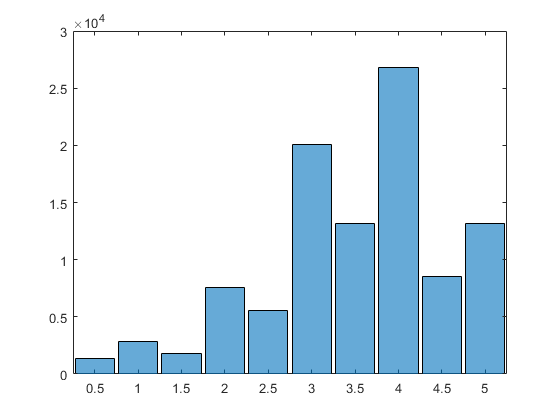

histogram(categorical(ratingsTbl.rating))

From the results, it appears that the ratings are biased towards higher ratings and that there is a clear preference toward whole-number ratings.

## Combine the rating and movie `tables`

While keeping a separate dictionary table like `moviesTbl` would usually save memory - as the title and genre information is not repeated for every rating of that movie - this advantage is largely negated when working with out-of-memory data. Therefore we will combine the data in `ratingsTbl` and `moviesTbl` by *joining* them on their common variable, `movieId`, using the [`join`](https://www.mathworks.com/help/matlab/ref/table.join.html) function. (This is different than the `join` method for `string` variables used earlier.) By joining the two tables, computations involving information from both tables will be simplified.

### Left joins

If you have previously worked with databases, you are probably already familiar with [join operations](https://en.wikipedia.org/wiki/Join_(SQL)) as they are commonly used for combining and working with data stored in multiple databases. There are many different types of joins- the one discussed below is referred to as a left-join. As stated above we wish to form a single table that combines the information in ratings table and the movie dictionary table to simplify analysis that uses information from each. In the present case:

- Both `ratingsTbl` and `moviesTbl` share a common or 'key' variable, `movieId`.

- `moviesTbl` only contains a single row for each unique `movieId` value.

- `ratingsTbl` contains *multiple rows* for most `movieId` values as most of the movies have been reviewed multiple times.

By left-joining the ratings `table` with the dictionary `table`, we will effectively of 'broadcast' a copy of each non-key row of `moviesTbl` to the corresponding rows of `ratingsTbl` that share the same movie ID. Any movies listed in `moviesTbl` whose ID *is not* contained in `ratingsTbl` (i.e. the movie was in the dictionary but not rated) will be ignored. The resulting table will contain the same number of rows as `ratingsTbl` with the additional title and genre information carried over from `moviesTbl`. See the documentation for more information on joining tables using `join`.

### Joining a `tall` table

Because `ratingsTbl` is a `tall` `table`, the additional information from `moviesTbl` will be added to the ratings data* automatically* as chunks of data are read in from the csv file. This is different from an in-memory `table` where this information would be immediately added to the `table` variable (increasing its memory footprint). Also, no data (additional columns) will be added to the original data file, ratings.csv. 

    Run the code below to join `ratingsTbl` and `moviesTbl` on `movieId` and examine the results.

ratingsTbl = join(ratingsTbl,moviesTbl)

#### **Obtain a list of *****unique***** movie ID's and update the ID's in **`ratingsTbl` 

The ratings dataset contains movie ratings organized by user, so that the dataset contains at least one rating from each user ID from 1 to the number of unique users in the dataset, `nu`. However, *the same is not true for movie ID's* as some movies in the original dataset were not rated by any user in this subset, and thus there are 'gaps' in the set of movie ID's that appear in `ratingsTbl`. To simplify later analysis, we use the `findgroups` function below to assign a new movie ID to each movie present in `ratingsTbl`, such that the movie ID's then form a contiguous set of integers from 1 to the number of unique movies in the dataset, `nm`. Run the code below to update the ratings `table` with the new movie IDs and obtain the number of unique movies in the dataset. 

[grp,inds] = findgroups(ratingsTbl.movieId);
inds = gather(inds);
nm = length(inds);
fprintf('There are %d unique movies in the ratings dataset',nm)
ratingsTbl.movieId = grp

Now that we have combined the ratings and movie information into a single `table` and obtained a contiguous set of movie ID's, it will be easier to perform analysis that involve both sets of information as in the next few examples.

#### **Identify the most reviewed movie**

Run the code below to obtain the number of ratings for each movie in `movieId` and store it in the variable `numRatings`, then find the most reviewed movie in the dataset. The distribution of ratings/movie is also visualized. 

numRatings = gather(histcounts(ratingsTbl.movieId,'BinMethod','integers'));
[count,ind] = max(numRatings);
ttl = gather(ratingsTbl.title(find(ratingsTbl.movieId==ind,1)));
fprintf('The most reviewed movie in the dataset is ''%s'' with %d reviews',ttl, count);
histogram(numRatings,'BinWidth',10)
xlabel('# of Reviews')

From the results, it's clear that the majority of movies have been rated by 10 or fewer users. 

#### **Calculate the mean ratings for the Star Wars trilogies**

Run the code below to create a list of titles corresponding to the original (IV - VI) and the prequel (I - III) Star Wars trilogies, then obtain the mean rating for each group.

titles = "Star Wars: Episode " + ["IV","V","VI"] + " "
inds = contains(ratingsTbl.title,titles);
rtg =  gather(mean(ratingsTbl.rating(inds)));
fprintf('The mean rating for the original Star Wars trilogy is: %.2f',rtg);
titles = "Star Wars: Episode " + ["I","II","III"] + " "
rtg = gather(mean(ratingsTbl.rating(contains(ratingsTbl.title,titles))));
fprintf('The mean rating for the Star Wars prequels is: %.2f',rtg);

#### Calculate and plot the mean rating of movies by release year

Grouping functions like `grpstats` and `findgroups` can be applied on `tall` data with the additional step that their outputs must be gathered. Run the code below to calculate the mean movie rating by release year and the total number of ratings for movies released that year. The results are then plotted by year on the same axis using the [`yyaxis`](https://www.mathworks.com/help/matlab/ref/yyaxis.html) function before being plotted vs each other. 

[means,sums,grp] = grpstats(ratingsTbl.rating,ratingsTbl.year,{'mean','numel','gname'});
[means,sums,grp] = gather(means,sums,grp);
figure; hold on;
yyaxis left;
plot(str2double(grp),means,'b.','MarkerSize',6);
yyaxis right;
plot(str2double(grp),sums,'rsq','MarkerSize',6);
legend({'Mean rating','# of ratings'})
figure;
plot(sums,means,'diamond')
title('Ratings grouped by year')
xlabel('Number of ratings')
ylabel('Mean rating')

#### Perform your own analysis!

Use this section to perform your own analysis or create your own visualizations using the data in `ratingsTbl`. Do not overwrite existing any variable names or modify `ratingsTbl` as they are used in the next section.

% Your code here!




## Two simple recommender systems

In the next section we will use a `sparse` matrix to build a nearest neighbors recommender system and in the last section we will build a collaborative filtering recommender system similar to the one you created in ex8. Before implementing these more complicated systems, however, we'll first use two (much) simpler recommender systems for comparison.

#### Predict the overall mean rating for all movies

Perhaps the simplest recommender system to implement is to predict the mean of *all *movie ratings for new movies and users (this value was computed the previous section as `globalMean` $\approx$ 3.5). This system takes into account the performance of all movies when predicting the rating, but not *individual *movie or user information. To measure the value of this simple system and offer a performance comparison with the more complicated recommender systems we'll create later, we'll compute the mean absolute prediction error over all existing ratings as a 'training error' and display the result.

err = gather(mean(abs(ratingsTbl.rating-globalMean)));
fprintf('The mean absolute prediction error using the overall mean rating is: %g',err);

#### Predict the mean rating for each movie

Consider now a slightly more complex recommender system that predicts the mean rating for each movie for all users*.* This system will likely perform and generalize better as it bases its recommendations on the performance of each movie separately. However, it may still suffer from poor generalization in cases where there are relatively few reviews for a particular movie, as one or two unusually good or bad reviews can have an outsized effect. Therefore we will implement a *slightly* smarter and more realistic system and use the mean movie rating for prediction *only if that movie has been reviewed at least 10 times*. Otherwise, we will predict the overall mean rating, `globalMean`. 

    Run the code below to compute the mean absolute prediction error using this system. You should see improvement over the previous system. The mean rating and the number of ratings for each movie are then added to `ratingsTbl` via another join operation. 

meanRating = gather(splitapply(@mean,ratingsTbl.rating,ratingsTbl.movieId));
ratingsTbl = join(ratingsTbl,array2table([(1:nm)',meanRating,numRatings'],'VariableNames',{'movieId','meanRating','numRatings'}));
meanPred = ratingsTbl.meanRating;
meanPred(ratingsTbl.numRatings<10) = globalMean;
meanPredErr = mean(abs(meanPred-ratingsTbl.rating));
fprintf('The mean absolute error when predicting the mean rating by movie is: %g',gather(meanPredErr))

## Explore movies by mean rating

Run the code below to create a new movie dictionary `table` containing the movie ID, title, year, mean rating, number of ratings, and genres of each movie in `ratingsTbl`. After the resulting `table` is displayed, use the Live search, sorting and filtering options to explore the movie ratings using the title, year, number of ratings, genre or a combination of these variables. To access the sorting and filtering options:

- Hover over or click on a variable name (e.g. 'year')

- Click on the black triangle when it appears. A list of available options for searching, sorting, and filtering will be shown (the exact options depend on the variable datatype). 

See the example screen capture below where the options for the numeric variable 'year' have been displayed:

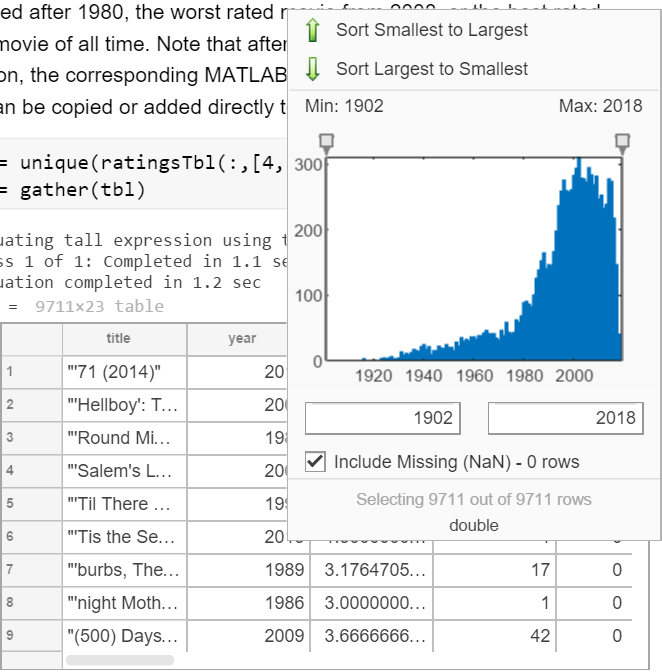

For example, can you find: 

- The mean rating of a specific movie? (Hint: Open the title options then select 'Clear All' before entering a specific title into the search bar).

- The best rated movies with at least 25 ratings released after 1980?

- The worst rated movie from 2008 with at least 10 ratings?

- The horror movie with the most ratings? 

Tips:

- To undo a sort operation you can override it by sorting on a different variable

- To undo multiple sort and filter options rerun this section to generate a new table.

- Perform filtering operations first, then sort. 

tbl = unique(ratingsTbl(:,[2,4,5,end-1,end,6:end-2]),'rows');
tbl = gather(tbl)

Note: After you perform a Live sorting or filtering operation, the corresponding MATLAB code is automatically displayed. This code can be copied to the clipboard or added directly to the script to programmatically replicate those operations results in the future. 

# Build a Nearest Neighbors Recommender System Using `sparse` Matrices

In this section we construct a nearest neighbors recommender system using `sparse` arrays.

## Introduction

The recommender systems so far have only taken into account information about *the movies* when estimating ratings, while information about *the users* was ignored. In this section we implement a nearest neighbors recommender that builds on the first two, but also takes into account the preferences of individual users. The main ideas behind a nearest neighbor recommender are as follows:

- Compute the pairwise distance between users- in this case we will use the average absolute difference of their ratings on common movies.

- For each user, obtain a list of 'close' users (neighbors) as judged by 1.

- For a movie that a given user hasn't rated- predict the mean neighbor rating for that movie.

## Adjustments for sparse datasets  

Due to the sparsity of the movie rating data, however, here are several complications:

- The majority of user pairs will share few or 0 rated movies in common resulting in artificially small or large distances.

- There will be many users who have very few neighbors.

- Even for users who have many neighbors, there will be some movies that few or none of their neighbors have rated.

Clearly the performance of nearest neighbors depends largely on the size of the data set, with bigger being better to maximize the number of neighbors. To help address the above issues, we will adopt the following criteria in our implementation:

- If a user pair does not share at least `minInCommon` rated movies they cannot be considered as neighbors.

- When predicting ratings for a given user and movie, if the number of neighbor ratings is less than `minRtgs`, we instead predict the mean rating* of that movie.

- Instead of using the MATLAB [`knnsearch`](https://www.mathworks.com/help/stats/knnsearch.html) function to obtain a fixed number of neighbors, we will use the [`rangesearch`](https://www.mathworks.com/help/stats/rangesearch.html) to obtain a list of all neighbors for each user with a distance less than a maximum distance, `maxdist`.

In the next few sections, we will implement a nearest neighbors movie recommender system with the modifications described above. 

## Create a `sparse` ratings matrix 

The MATLAB nearest neighbor functions mentioned above accept data matrices as input. In the current example this would be a matrix of ratings where the rows correspond to a given user and the columns correspond to a given movie. As the majority of movies in the dataset have not been rated by any given user, however, it does not make sense to work with a 'full' matrix of ratings where the vast majority of elements would be 'empty'. These elements would take up a lot of memory but wouldn't provide additional value. A better option in such cases is to the data in a [`sparse`](https://www.mathworks.com/help/matlab/sparse-matrices.html) matrix.

 To create a `sparse` matrix in MATLAB, we provide the row indices, column indices, and values for each nonzero element. Sparse matrices are discussed further in the next few sections. Run the code below to import the rating into a sparse matrix, `R`, where `R(i,j)` corresponds to the rating by user `i` of movie `j`.

clearvars -except R ratingsTbl ratingsDS tbl globalMean
[userId,movieId,rating] = gather(ratingsTbl.userId,ratingsTbl.movieId,ratingsTbl.rating);
R = sparse(userId,movieId,rating);

### **Working with **`sparse`** arrays**

- A `sparse` array requires only enough space to store nonzero elements and their indices, as all other elements are considered to have a value of 0.

- Many common MATLAB operations and functions are optimized for sparse inputs and will run faster than with the corresponding full matrices. 

- `sparse` arrays can be manipulated, [accessed](https://www.mathworks.com/help/matlab/math/accessing-sparse-matrices.html), and used in calculations using the same syntax as with full arrays. 

- Any subsets extracted from a `sparse` array are returned as a `sparse` arrays, even if they contain only a single element or all non-zero elements. 

- Use the [`find`](https://www.mathworks.com/help/matlab/ref/find.html) function to obtain the indices of nonzero elements.

- Use the [`nonzeros`](https://www.mathworks.com/help/matlab/ref/nonzeros.html) function to extract only the nonzero elements.

- Use the [`full`](https://www.mathworks.com/help/matlab/ref/full.html) function to convert a `sparse` array to a full array.

Run the examples in the next few sections and examine the results to get better acquainted with `sparse` matrices.

- Access a zero and nonzero element of a `sparse` array and view the results

R(1,1)
R(2,1)

- Access a subset of a `sparse` array

R(:,1)

- Use the `find` function to obtain the row and column indices of nonzero elements in the last column of a sparse array

[r,c] = find(R(:,1))

- Use the `nonzeros` function to obtain the values non-zero elements in the first column of a `sparse` array

nonzeros(R(:,1))

- Use the `full` function to convert the first column of a `sparse` array into a full (`double`) array

full(R(:,1))

- Use the `size` function to obtain the number of users and movies (rows and columns) in `R`

[nu,nm] = size(R)

## Add your own movie ratings to the dataset

#### Search for a movie

Run the code below to display the movie dictionary table `tbl`. The use the search option to search for a movie and obtain the movie ID value. 

- Hover over the 'title' variable in the table until a triangle appears.

- Click the triangle to open the search and sort options for 'title'

- Select 'Clear all' to remove all movies

- Enter a movie title in the 'Search' bar. Search results will appear as you type.

- Select the box of the correct result and that movie row will appear in the `table`. You can select more than one movie.

- Enter the movie ID(s) in the next section along with your rating.

After adding your rating in the next section, return to this section and repeat the steps to search for and obtain the movie ID of a different movie. If your movie wasn't found in the database, try a new search.

tbl

#### Add your ratings to `R`

Enter the movie ID you obtained in the previous section and your rating. Then run this section to add your rating to `R`. A list of your ratings is displayed for reference. Try to rate at least 10 movies for better recommendations.

movieid = 6; % Add the index from the search results
rating = 4; % Select your rating
R(nu+1,movieid) = rating;
% Your ratings:
table(tbl.title(R(end,:)>0),nonzeros(R(end,:)),'VariableNames',{'Movie','Rating'})

## Obtain a list of neighbors using `rangesearch`

In this section we'll use the [`rangesearch`](https://www.mathworks.com/help/stats/rangesearch.html) function to compute a list of neighbors for each user whose distance is less than `maxdist`. We'll use a custom distance function, `nndistfun`, which is defined at the end of this Live Script. `nndistfun` will compute the pairwise distances between users such that:

- The distance between two users is the mean absolute difference of their ratings on common movies.

- Only users that share at least `minInCommon` movies can be considered neighbors. 

Note that the model hyperparameters `minInCommon`, `maxdist`, and `minrtgs` will vary depending on the size and sparsity of the data set. The `rangesearch` function will return a cell array of neighbors for each user whose distances are less than `maxdist`. Run the code below to obtain the neighbor list and display  your neighbors.

minInCommon = 3;
maxDist = 0.75;
minRtgs = 3;
nbrlist = rangesearch(R,R,maxDist,'Distance',@(x,Y)nndistfun(x,Y,minInCommon));
disp('Your neighbor id''s: ')
nbrlist{end}'

## Predict movie ratings using nearest neighbors

We have implemented a nearest neighbors prediction function at the end of this Live Script, `nnpredictfun`. For a given user and movie, this function will return an estimated rating for that movie given by either:

- The mean rating of all neighbor ratings for that movie, provided at least `minrtgs` neighbors have rated that movie from neighbors.

- The mean rating for that movie in the case fewer than `minrtgs` neighbors have rated that movie and the movie has at least 10 ratings.

- The mean rating of all movies if fewer than `minrtgs` neighbors have rated the movie and the total number of ratings by all users is less than 10.

### Compute the mean absolute prediction error

Run the code in this section to compute the mean absolute prediction error. The percentage of predictions made using neighbor ratings (instead of the mean movie rating) is also retuned. Compare to the corresponding errors when using the overall or the individual rating means for prediction.

[pred,nnOrMean] = nnpredictfun([userId,movieId],nbrlist,R,tbl,minRtgs);
fprintf('The mean absolute error for the nearest neighbor method is: %g', mean(abs(pred-gather(ratingsTbl.rating))));
fprintf('Neighbor ratings were used to make %g percent of predictions.',100*mean(nnOrMean))

### Estimate your own ratings using nearest neighbors

The code below will estimate your movie rating using nearest neighbors and add them to the movie `table` created previously as the variable `myNNrating`. As before, you can use the search, sort, and filter options in to explore your recommendations and compare with the mean movie ratings. 

myNNrating = nnpredictfun([ones(nm,1)*(nu+1),(1:nm)'],nbrlist,R,tbl,minRtgs);
tbl = addvars(tbl,myNNrating,'After','meanRating')

# Build a Collaborative Filtering Recommender System Using `sparse` Matrices 

In ex8 you implemented a collaborative filtering recommender to predict movie ratings for users and movie ratings stored in a matrix, $Y$. As discussed in the previous section, for larger sets of ratings it is prohibitive to store *all* of the elements in $Y$ *as well as* an 'indicator' matrix $R$ due to their relative sparsity. In the next few sections we provide an alternative implementation using the `sparse` ratings matrix `R` created in the previous section.

## Introduction

Recall that the main idea behind the collaborative filtering algorithm was to approximate a ratings matrix which we denote $R$, where $R_{ij}$ corresponds to the rating by user $i$ of movie $j.$ The goal was to factorize $R$ into two smaller matrices, $X$ and $\Theta$, such that their product $\tilde{R} = X\Theta\approx R$ over the set of existing ratings. In terms of the rows and columns of $X$ and $\Theta$, the elements of $\tilde{R}$ are given by the product $\tilde{R}_{ij}=x^{(i)}\;\theta_{(j)}$, where:

- $x^{(i)}$ is the $i$th *row *of $X$

- $\theta_{(j)}$ is the $j$th *column* of $\Theta$

The sizes of $X$ and $\Theta$ were determined by the number of users $n_u$, the number of movies $n_m$, and the number of 'latent features', $n_f$ such that:

- $X$ is an $n_u\times n_f$ matrix of weights corresponding to each user and feature

- $\Theta$ is an $n_f\times n_m$ matrix of weights corresponding to each feature and movie

- $\tilde R = X\Theta$ is an $n_u\times n_m$ matrix of predicted ratings

The number of latent features ultimately depends on the complexity of the data, where more features are in general required to capture more complex data. This parameter can be tuned using cross-validation.

## Bias terms and cost function

In the implementation that follows, we provide a slightly more complex method for approximating $R_{ij}$ that incorporates bias terms for each user and movie to help capture general aspects of the dataset, as certain users and movies tend to rate or be rated higher or lower than others overall. Adding the bias terms, our approximation becomes:


$$\tilde{R}_{ij} = x^{(i)}\; \theta_{(j)}+b_{i}^u+b_{j}^m+\mu \approx R_{ij} $$


where:

- $b^u$ is a length $n_u$ vector of bias terms, and $b_{i}^u$ is the user bias term for user $i$.

- $b^m$ is a length $n_m$ vector of bias terms, and $b_j^m$ is the movie bias term for movie $j$.

- $\mu$ is a fixed, 'global' bias term equal to the mean of all movie ratings.

The values $X$, $\Theta$, $b^u$ and $b^m$ can be obtained in the same fashion as in ex8 by minimizing the cost function:


$$J=\frac{1}{2}\sum_{(i,j)\in I}{\left(R_{ij}-\tilde{R}_{ij}\right)^2}+\frac{\lambda}{2}\left(\sum_{i,k}X_{ik}^2+\sum_{k,j}\Theta_{kj}^2\right)$$


where:

- $I$ is the set of pairs $(i,j)$ such that user $i$ has rated movie $j$.

- $\lambda$ is the regularization strength.

- We do not regularize the bias terms.

## Initialize parameters and run gradient descent

A gradient descent training algorithm has already been implemented as a local function, `cofiGrad`, at the end of this script. Run the code below to train a recommender system (obtain the $X$ and $\Theta$ factor matrices and the bias terms) until the mean absolute prediction error falls below the value set by `tol` below. This will take several minutes to run. We have selected an initial value of 100 for `nf` (the number of latent features), but this can be changed along with the regularization penalty `lambda` if you are curious about their effects. Note that you may have to increase the tolerance in cases where you decrease `nf` or increase `lambda` so that the algorithm will converge within the maximum number of iterations allowed.

tol = 0.2; % Target mean absolute prediction error on existing ratings
lambda = 0.5; % Regularization strength
nf = 100; % Number of latent features
[X,Theta,movieBias,userBias] = cofiGrad(R,nf,tol,lambda);

## Estimate your own ratings using collaborative filtering

The code below will estimate your movie ratings using nearest neighbors and add them to the movie `table` as the variable `myCofiRating`. As before, you can use the search, sort, and filter options in to explore your recommendations and compare with the mean movie ratings. For better comparison with the nearest neighbor predictions we will set the predictions for movies with less than 10 ratings to the global mean rating.

myCofiRating = (X(end,:)*Theta+movieBias+userBias(end)+globalMean)';
myCofiRating(tbl.numRatings < 10) = globalMean;
tbl = addvars(tbl,myCofiRating,'After','myNNrating')

## Save your ratings

Now that you have some recommendations for movies you might enjoy and some you might want to avoid, run the command below to use the [`writetable`](https://www.mathworks.com/help/matlab/ref/writetable.html) function save them to a csv file to help guide your future viewing. You can also go back and add more ratings to improve your recommendations further, or add filtering commands to select the genres or release years you are most interested in or sort/filter by mean rating or your predicted rating by adding the generated code below.

% Add sorting and filtering commands for your
% table here:


writetable(tbl,'MovieRecommendations.csv')

# Local Functions

## `nndistfun`

Nearest neighbor distance function. This function returns the mean absolute distance between ratings over shared movies and sets any user-pair distance with less than `minInCommon` shared ratings to the maximum distance.

function Dist = nndistfun(x,Y,minInCommon)
maxdist = 4.5; % maximum possible distance
n = size(Y,1);
Dist = zeros(n,1);
inds = x == 0; % movies not rated by user
x(inds) = [];
Y(:,inds) = [];
inCommon = sum(Y>0,2); % num shared movies
inds = inCommon < minInCommon;
Dist(inds) = maxdist;
Y(inds,:) = [];
%X = repmat(x,size(Y,1),1);
%X(Y==0) = 0; % Set movie ratings not rated by both users to 0
dist = sum(abs(x.*(Y>0)-Y),2)./inCommon(~inds); % average absolute difference in shared ratings
Dist(~inds) = dist;
end

## `nnpredictfun`

Nearest neighbor prediction function:

function [pred,nnOrMean] = nnpredictfun(Inds,nblist,ratings,movietbl,minRtgs)
n = size(Inds,1); % number of ratings to compute
pred = zeros(n,1); % vector of predicted movie ratings
nnOrMean = logical(pred); % keep track of whether mean or nn used to compute rating
globalMean = mean(nonzeros(ratings));
for k = 1:n
    uid = Inds(k,1); % userId
    mid = Inds(k,2); % movieInd
    neighbors = nblist{uid}; % neighbors
    neighbors(neighbors == uid) = []; % remove 'self' neighbor
    rtgs = ratings(neighbors,mid); % movie ratings by neighbors
    if nnz(rtgs) > minRtgs
        pred(k) = mean(nonzeros(rtgs));
        nnOrMean(k) = 1;
    elseif movietbl.numRatings(mid) > 10
        pred(k) = movietbl.meanRating(mid);
    else
        pred(k) = globalMean;
    end
end
end


## cofiGrad

Gradient descent algorithm for training the collaborative filtering parameters. A user-mini-batch gradient descent algorithm is implemented below such that the partial gradient is calculated and an optimization step taken using the ratings from a single user. The batch size is therefore variable and depends on the number of user ratings. After all users are iterated through, the list of users is randomized before the next iteration.

function [X,Theta,movieBias,userBias] = cofiGrad(R,nf,tol,lambda)
% Initialize coefficient matrices
[users,movies,ratings] = find(R);
nu = length(unique(users));
nm = length(unique(movies));
X = randn(nu,nf);
Theta = randn(nf,nm);
movieBias = zeros(1,nm);
userBias = zeros(nu,1);
globalMean = mean(ratings);
% Initialize gradient descent parameters
err = tol;
alpha = 0.02;
maxit = 200;
it = 0;
while (err >= tol) && (it < maxit)
    it = it+1;
    % Display progress
    if (round(it/20)-it/20 == 0)
        fprintf('Iteration: %d | Mean absolute error: %g | Max absolute error: %g\n',it,err,max(abs(E)));
    end
    E = [];
    for i = randperm(nu)
        [~,J] = find(R(i,:));
        r = full(R(i,J));
        Err = r-(X(i,:)*Theta(:,J)+userBias(i)+movieBias(J)+globalMean);
        E = [E Err];
        dX = Err*Theta(:,J)'-lambda*X(i,:);
        dTheta = X(i,:)'*Err-lambda*Theta(:,J);
        dmovieBias = Err;
        duserBias = sum(Err);
        % adjust alphas for numerical stability
        alphax = alpha/max(abs(dX(:)));
        alphat = alpha/max(abs(dTheta(:)));
        alphamb = alpha/max(abs(dmovieBias(:)));
        alphaub = alpha/max(abs(duserBias(:)));
        % Update coefficients
        X(i,:) = X(i,:)+alphax*dX;
        Theta(:,J) = Theta(:,J)+alphat*dTheta;
        movieBias(J) = movieBias(J)+alphamb*dmovieBias;
        userBias(i) = userBias(i)+alphaub*duserBias;
    end
    err = mean(abs(E));
end
fprintf('Final Iteration: %d | Final mean absolute error: %g | Final max absolute error: %g',it,err,max(abs(E)));
end